### Filtros

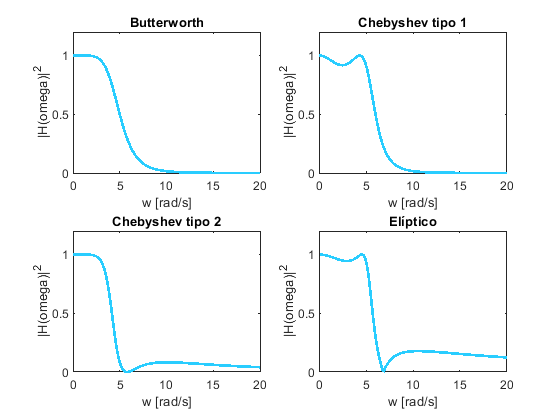

cutFrequency = 5;

frequencies = linspace(0,20,1000);

order = 3;

sigma = 0.3;
responseButterworth = 1./(1 + (frequencies./(cutFrequency)).^(2*order));
responseChebyshev1 = 1./(1 + (sigma^2)*chebyshevT(order,frequencies./cutFrequency).^2);
responseChebyshev2 = ((sigma^2)*chebyshevT(order, cutFrequency./frequencies).^2)./(1 + (sigma^2)*chebyshevT(order, cutFrequency./frequencies).^2);

[ze,pe,ke] = ellip(3,0.5,15,5,'s');
[be,ae] = zp2tf(ze,pe,ke);
[he,we] = freqs(be,ae,1000);


figure()
subplot(2,2,1)
plot(frequencies, responseButterworth, 'Color', "#29cdff", 'LineWidth', 2)
xlabel("w [rad/s]")
ylabel("|H(omega)|^{2}")
title("Butterworth")
ylim([0,1.2])
subplot(2,2,2)
plot(frequencies, responseChebyshev1, 'Color', "#29cdff", "LineWidth", 2)
xlabel("w [rad/s]")
ylabel("|H(omega)|^{2}")
title("Chebyshev tipo 1")
ylim([0,1.2])
subplot(2,2,3)
plot(frequencies, responseChebyshev2,'Color', "#29cdff", "LineWidth", 2)
xlabel("w [rad/s]")
ylabel("|H(omega)|^{2}")
title("Chebyshev tipo 2")
ylim([0,1.2])
subplot(2,2,4)
plot(we, abs(he), 'Color', "#29cdff", "LineWidth", 2)
xlabel("w [rad/s]")
ylabel("|H(omega)|^{2}")
title("Elíptico")
ylim([0,1.2])
xlim([0,20])

#### Prueba filtro manual

La función de transferencia es de la forma:


$$H\left(z\right)=\frac{\sum_{k=0} b_k z^{-k} }{1+\sum_{k=1} a_k z^{-k} }$$


Al seguir los pasos para discretizar el filtro Butterworth, para una frecuencia de corte de 25.2 Hz lo que se obtuvo fue 


$$H\left(z\right)=\frac{0\ldotp 000863271\;z^{-1} +0\ldotp 000863271}{1-{0\ldotp 726543z}^{-1} }$$
 

Así que nuestro filtro Butterworth tiene:


$$b_0 =b_1 =0\ldotp 289596\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;a_1 =-0\ldotp 158384\;\;$$


Apliquemos nuestro filtro a una señal chirp para ver si funciona

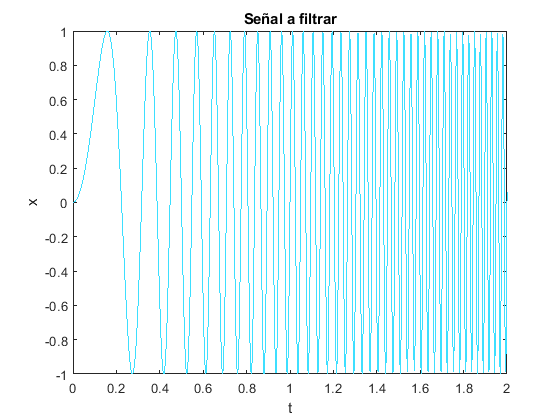

t0 = 0;
tf = 10;
f0 = 0;
ff = 100;

nData = 5000;
tArray = linspace(0,10,nData);
parameterArray = linspace(0,1,nData);
xArray = sin(2*pi*(f0 + (ff - f0).*parameterArray).*tArray);

figure()
plot(tArray, xArray, "Color", "#3ddfff")
title("Señal a filtrar")
xlabel("t")
ylabel("x")
xlim([0,2])

%xlim([0,2])

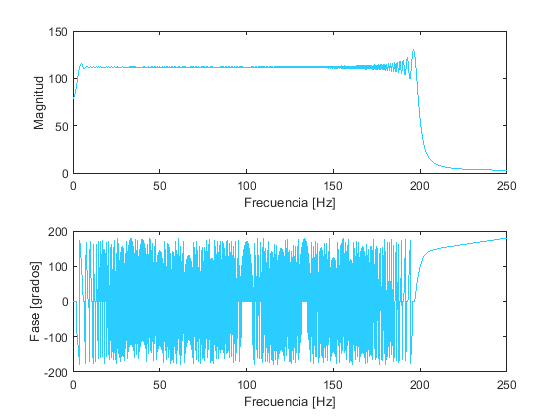

%Espectro de la señal a filtrar

spectrumPlotter = SpectrumPlotter();
[normalFrequencies, normalMagnitude, normalPhase] = spectrumPlotter.spectrumNormalScale(tArray, xArray);

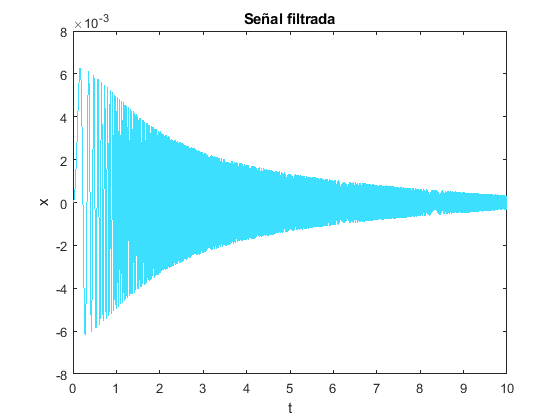

aCoeffs = [-0.726543];
bCoeffs = [0.0008663271, 0.000863271];
filterer = Filterer();
xFiltered = filterer.applyIIRFilter(xArray, aCoeffs, bCoeffs);


figure()
plot(tArray, xFiltered, "Color", "#3ddfff")
title("Señal filtrada")
xlabel("t")
ylabel("x")

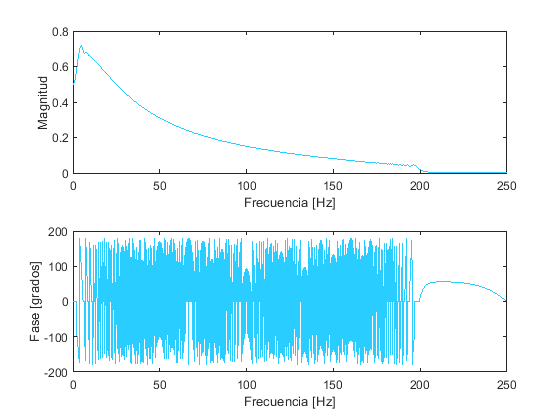

spectrumPlotter = SpectrumPlotter();

[freqsFiltered, magFiltered, phaseFiltered] = spectrumPlotter.spectrumNormalScale(tArray, xFiltered);

maxMag = max(magFiltered);
epsilon = 0.001;
cutFreq = 0;
amplitudeCut = (1/sqrt(2))*maxMag;
for i = 1:length(freqsFiltered)
    if(magFiltered(i) > amplitudeCut - epsilon && magFiltered(i)<amplitudeCut + epsilon)
        cutFreq = freqsFiltered(i)
    end
end

cutFreq = 0.5999

cutFreq = 24.1952

cutFreq = 24.2951

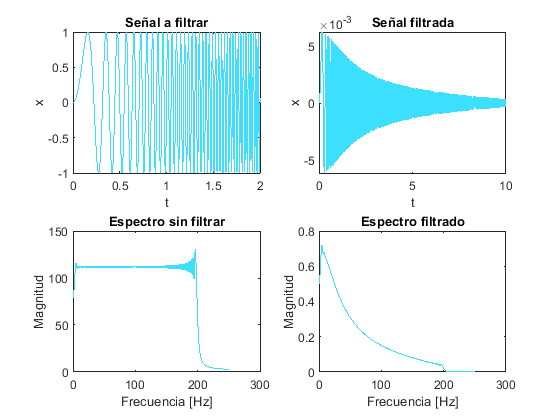

figure()
subplot(2,2,1)
plot(tArray, xArray, "Color", "#3ddfff")
title("Señal a filtrar")
xlabel("t")
ylabel("x")
xlim([0,2])
subplot(2,2,2)
plot(tArray, xFiltered, "Color", "#3ddfff")
title("Señal filtrada")
xlabel("t")
ylabel("x")
subplot(2,2,3)
plot(normalFrequencies, normalMagnitude,"Color", "#3ddfff" )
title("Espectro sin filtrar")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")
subplot(2,2,4)
plot(freqsFiltered,magFiltered,"Color", "#3ddfff" )
title("Espectro filtrado")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")

### Uso de las funciones para obtener filtros de MATLAB

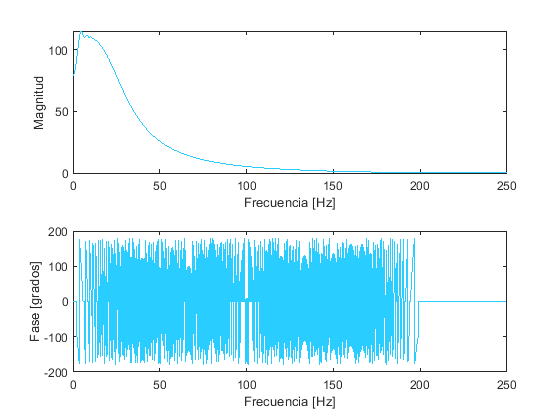

fCut = 25;
fs = 1/(tArray(2) - tArray(1));
w = fCut/(fs/2);

%Butterworth
[bButter, aButter] = butter(2, w);
filteredButter = filterer.applyIIRFilter(xArray, aButter(2:end), bButter);
[freqsButter, magButter, phaseButter] = spectrumPlotter.spectrumNormalScale(tArray, filteredButter);

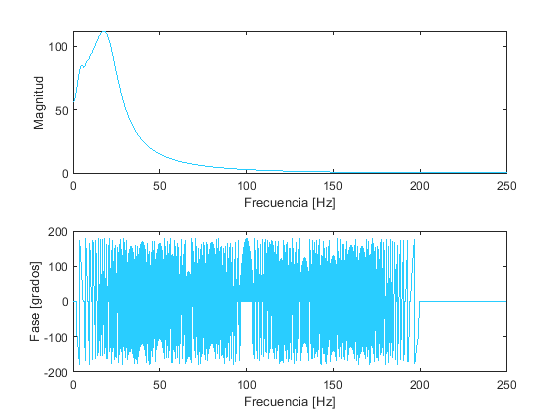


%Chebyshev 1
[bCheby1,aCheby1] = cheby1(2,3,w);
filteredCheby1 = filterer.applyIIRFilter(xArray, aCheby1(2:end), bCheby1);
[freqsCheby1, magCheby1, phaseCheby1] = spectrumPlotter.spectrumNormalScale(tArray, filteredCheby1);

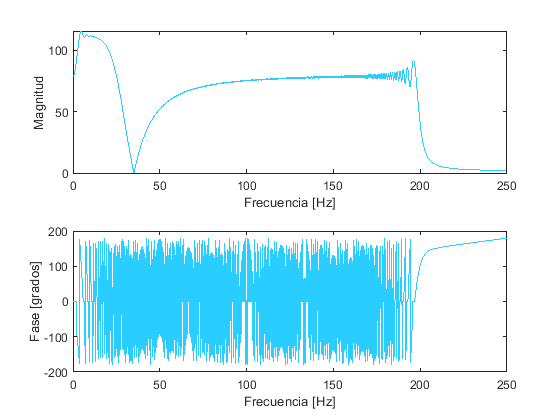

%Chebyshev 2
[bCheby2,aCheby2] = cheby2(2,3,w);
filteredCheby2 = filterer.applyIIRFilter(xArray, aCheby2(2:end), bCheby2);
[freqsCheby2, magCheby2, phaseCheby2] = spectrumPlotter.spectrumNormalScale(tArray, filteredCheby2);

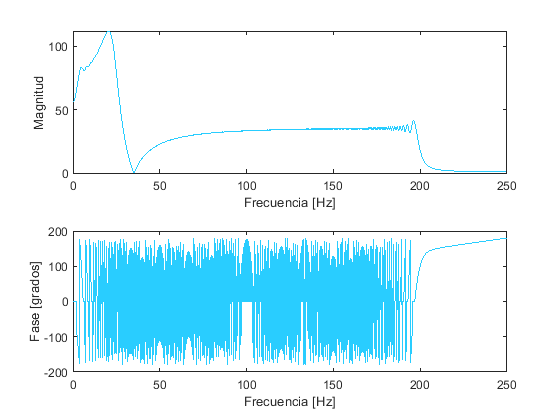

%Elliptic
[bElliptic, aElliptic] = ellip(2, 3, 10, w);
filteredElliptic = filterer.applyIIRFilter(xArray, aElliptic(2:end), bElliptic);
[freqsElliptic, magElliptic, phaseElliptic] = spectrumPlotter.spectrumNormalScale(tArray, filteredElliptic);

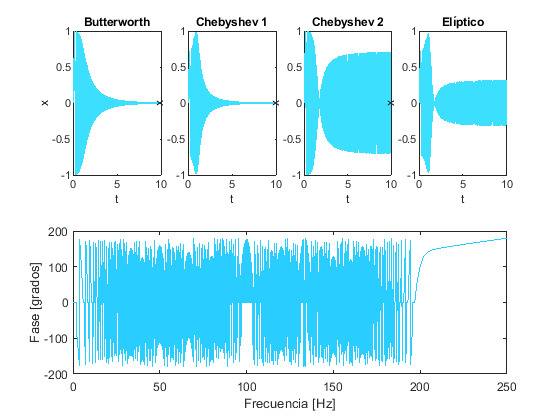


subplot(2,4,1)
plot(tArray, filteredButter, "Color", "#3ddfff")
title("Butterworth")
xlabel("t")
ylabel("x")

subplot(2,4,2)
plot(tArray, filteredCheby1, "Color", "#3ddfff")
title("Chebyshev 1")
xlabel("t")
ylabel("x")


subplot(2,4,3)
plot(tArray, filteredCheby2, "Color", "#3ddfff")
title("Chebyshev 2")
xlabel("t")
ylabel("x")

subplot(2,4,4)
plot(tArray, filteredElliptic, "Color", "#3ddfff")
title("Elíptico")
xlabel("t")
ylabel("x")

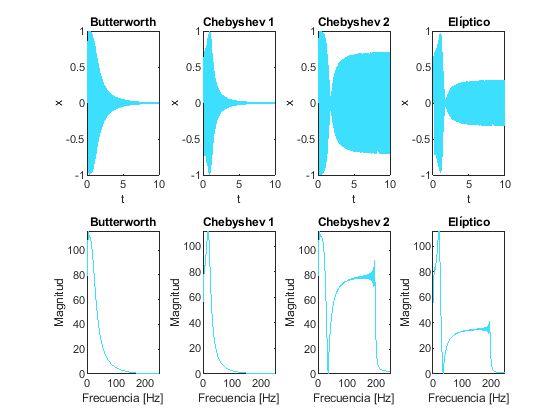


subplot(2,4,5)
plot(freqsButter, magButter, "Color", "#3ddfff")
title("Butterworth")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")

subplot(2,4,6)
plot(freqsCheby1, magCheby1, "Color", "#3ddfff")
title("Chebyshev 1")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")

subplot(2,4,7)
plot(freqsCheby2, magCheby2, "Color", "#3ddfff")
title("Chebyshev 2")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")

subplot(2,4,8)
plot(freqsElliptic, magElliptic, "Color", "#3ddfff")
title("Elíptico")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")